# Homework 3: Tic tac toe

The goal of this exercise to write a computer program that trains two players to play tic-tac-toe by playing against each other.

Two players learn how to play tic tac toe with Q-learning. Train the two players simultaneously, playing against each other. The goal is to find a Q-table ensuring that the player never loses, see Section 11.5 in the Lecture notes. Use the \varepsilon*ε*-greedy policy, start with a suitable value of $\varepsilon$ , and let $\varepsilon$ tend to zero as training progresses.

Each player has his/her own Q-table. For an efficient implementation, do not initialise your Q-tables for every possible state of the tic tac toe board. Instead only initialise Q-entries when they are enountered for the first time during training. To this end, write a function that checks whether a board configuration occurred previously, or not. If not, add it to your Q-table and initialise it.

You need to upload two csv files. One should be named "player1.csv" and describe the Q-table of the player going first. The other one should be called "player2.csv" for the player going second. The csv files should have the following structure: The first three lines should consist of all the board states known to your Q-table, horizontally appended. A board position is implented as a 3-by-3 block, where an "X" is represented by a "1", an "O" by a "-1" and an empty field by a "0". The next three lines mimic the structure of the boards in the first three lines, except here an entry represents the expected value for a move in that location. Move values for occupied locations should be represented by NaN entries.

The following image visualises the structure on the file "examplecsv.csv", which is also available to download.  Note that the specific numerical values in bottom three lines are not meaningful, they are only meant to demonstrate the structure of the file.

Hints: To easily obtain the desired .csv structure in Matlab, maintain the Q-table as a cell array with 2 rows and as many columns as there are known board states. In the first row, save a board state in every cell as a 3x3 matrix and in the second row the corresponding expected future rewards also as a 3x3 matrix with NaN entries on occupied fields. You can then use the function cell2mat followed by csvwrite to generate a .csv file with the right structure. The matlab function isnan can be very useful when debugging errors with the NaN entries. Note that Matlab evaluates arithmetic operations where one component is NaN entirely as NaN.

clc
clear
global Q1
global Q2
Q1 = cell(0);
Q2 = cell(0);
alpha = 0.1;
gamma = 1;
epsi = 1;
p1_wins = 0;
p2_wins = 0;
draws = 0;
p1_wins_list = zeros([1,300]);
p2_wins_list= zeros([1,300]);
draws_list = zeros([1,300]);

tic
for itr = 1:40000
    if ~mod(itr,100)
        epsi = epsi * 0.95;
        if 
        p1_wins_list(fix(itr/100)) = p1_wins/100;
        p2_wins_list(fix(itr/100)) = p2_wins/100;
        draws_list(fix(itr/100)) = draws/100;
        p1_wins = 0;
        p2_wins = 0;
        draws = 0;
    end

    if ~mod(itr,500)
        fprintf("iteration: %d", itr)
        toc
        tic
    end
    % borad init
    board = zeros(3);
    isend = 0;
    player = 1;

    ifseen(board, 1);
    [action_board, action_coord_1] = choose_action(board, epsi, player, 1);
    board_prime = board + action_board;
    player = ~player;
    
    ifseen(board_prime, 2);
    [action_board, action_coord_2] = choose_action(board_prime, epsi, player, 2);
    board_next = board_prime + action_board;
    
    ifseen(board_next, 1);
    update_Q(board, board_next, action_coord_1, 1, alpha, gamma, 0);
    player = ~player;
    board = board_next;
    while true
        %% P1 round
        board_prime_old = board_prime;
        [action_board, action_coord_1] = choose_action(board, epsi, player, 1);
        board_prime = board + action_board;
        isend = boardcheck(board_prime);
        if isend
            [R_1, R_2] = reward_assign(isend, player);
            fupdate_Q(board, action_coord_1, 1, alpha, gamma, R_1);
            fupdate_Q(board_prime_old, action_coord_2, 2, alpha, gamma, R_2);
            if R_1 == 1
                p1_wins = p1_wins + 1;
            elseif R_1 == 0
                draws = draws + 1;
            end
            break
        end
        ifseen(board_prime, 2);
        update_Q(board_prime_old, board_prime, action_coord_2, 2, alpha, gamma, 0);   
        player = ~player;

        %% P2 round
        [action_board, action_coord_2] = choose_action(board_prime, epsi, player, 2);
        board_next = board_prime + action_board;
        isend = boardcheck(board_next);
        if isend
            [R_1, R_2] = reward_assign(isend, player);
            fupdate_Q(board, action_coord_1, 1, alpha, gamma, R_1);
            fupdate_Q(board_prime, action_coord_2, 2, alpha, gamma, R_2);
            if R_2 == 1
                p2_wins = p2_wins + 1;
            elseif R_2 == 0
                draws = draws + 1;
            end
            break
        end
        ifseen(board_next, 1);
        update_Q(board, board_next, action_coord_1, 1, alpha, gamma, 0);
        player = ~player;
        board = board_next;
    end
end

iteration: 500

Elapsed time is 11.937722 seconds.


iteration: 1000

Elapsed time is 25.342753 seconds.


iteration: 1500

Elapsed time is 34.516228 seconds.


iteration: 2000

Elapsed time is 39.889117 seconds.


iteration: 2500

Elapsed time is 44.351995 seconds.


iteration: 3000

Elapsed time is 46.727161 seconds.


iteration: 3500

Elapsed time is 52.871429 seconds.


iteration: 4000

Elapsed time is 61.911272 seconds.


iteration: 4500

Elapsed time is 54.790741 seconds.


iteration: 5000

Elapsed time is 56.756259 seconds.


iteration: 5500

Elapsed time is 59.336188 seconds.


iteration: 6000

Elapsed time is 60.809046 seconds.


iteration: 6500

Elapsed time is 64.603805 seconds.


iteration: 7000

Elapsed time is 62.201542 seconds.


iteration: 7500

Elapsed time is 64.799126 seconds.


iteration: 8000

Elapsed time is 66.012830 seconds.


iteration: 8500

Elapsed time is 64.197599 seconds.


iteration: 9000

Elapsed time is 67.277191 seconds.


iteration: 9500

Elapsed time is 66.424099 seconds.


iteration: 10000

Elapsed time is 67.448254 seconds.


iteration: 10500

Elapsed time is 67.710339 seconds.


iteration: 11000

Elapsed time is 80.841477 seconds.


iteration: 11500

Elapsed time is 84.070923 seconds.


iteration: 12000

Elapsed time is 82.956686 seconds.


iteration: 12500

Elapsed time is 84.567880 seconds.


iteration: 13000

Elapsed time is 83.998885 seconds.


iteration: 13500

Elapsed time is 85.549152 seconds.


iteration: 14000

Elapsed time is 84.348025 seconds.


iteration: 14500

Elapsed time is 84.174032 seconds.


iteration: 15000

Elapsed time is 84.520563 seconds.


iteration: 15500

Elapsed time is 84.199143 seconds.


iteration: 16000

Elapsed time is 84.748246 seconds.


iteration: 16500

Elapsed time is 84.617082 seconds.


iteration: 17000

Elapsed time is 73.305362 seconds.


iteration: 17500

Elapsed time is 69.909124 seconds.


iteration: 18000

Elapsed time is 70.131863 seconds.


iteration: 18500

Elapsed time is 69.604743 seconds.


iteration: 19000

Elapsed time is 69.695051 seconds.


iteration: 19500

Elapsed time is 69.972951 seconds.


iteration: 20000

Elapsed time is 69.950965 seconds.


iteration: 20500

Elapsed time is 70.764128 seconds.


iteration: 21000

Elapsed time is 70.106854 seconds.


iteration: 21500

Elapsed time is 69.881687 seconds.


iteration: 22000

Elapsed time is 69.588928 seconds.


iteration: 22500

Elapsed time is 71.839874 seconds.


iteration: 23000

Elapsed time is 71.467973 seconds.


iteration: 23500

Elapsed time is 71.746511 seconds.


iteration: 24000

Elapsed time is 76.767012 seconds.


iteration: 24500

Elapsed time is 74.506265 seconds.


iteration: 25000

Elapsed time is 71.475661 seconds.


iteration: 25500

Elapsed time is 71.152463 seconds.


iteration: 26000

Elapsed time is 69.949435 seconds.


iteration: 26500

Elapsed time is 70.260894 seconds.


iteration: 27000

Elapsed time is 80.454844 seconds.


iteration: 27500

Elapsed time is 77.954400 seconds.


iteration: 28000

Elapsed time is 74.955100 seconds.


iteration: 28500

Elapsed time is 73.949588 seconds.


iteration: 29000

Elapsed time is 73.414935 seconds.


iteration: 29500

Elapsed time is 73.737894 seconds.


iteration: 30000

Elapsed time is 73.149292 seconds.


iteration: 30500

Elapsed time is 78.041575 seconds.


iteration: 31000

Elapsed time is 78.151299 seconds.


iteration: 31500

Elapsed time is 73.701381 seconds.


iteration: 32000

Elapsed time is 73.382606 seconds.


iteration: 32500

Elapsed time is 73.345570 seconds.


iteration: 33000

Elapsed time is 75.801660 seconds.


iteration: 33500

Elapsed time is 74.123750 seconds.


iteration: 34000

Elapsed time is 75.018188 seconds.


iteration: 34500

Elapsed time is 76.632368 seconds.


iteration: 35000

Elapsed time is 74.883207 seconds.


iteration: 35500

Elapsed time is 76.568300 seconds.


iteration: 36000

Elapsed time is 78.022248 seconds.


iteration: 36500

Elapsed time is 75.955636 seconds.


iteration: 37000

Elapsed time is 75.440080 seconds.


iteration: 37500

Elapsed time is 73.670890 seconds.


iteration: 38000

Elapsed time is 76.309826 seconds.


iteration: 38500

Elapsed time is 73.661829 seconds.


iteration: 39000

Elapsed time is 72.727505 seconds.


iteration: 39500

Elapsed time is 72.723956 seconds.


iteration: 40000

Elapsed time is 72.863154 seconds.


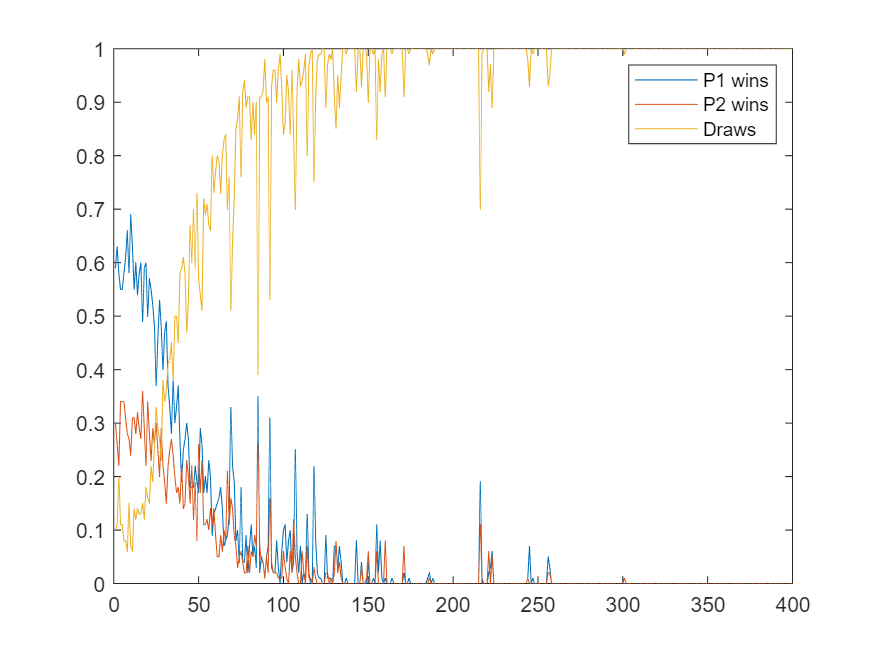

figure
plot(p1_wins_list)
hold on
plot(p2_wins_list)
plot(draws_list)
legend("P1 wins", "P2 wins", "Draws")

Q1_mat = cell2mat(Q1);
Q2_mat = cell2mat(Q2);
csvwrite("player1.csv", Q1_mat)
csvwrite("player2.csv", Q2_mat)

function Q = ifseen(board, Q)
    global Q1
    global Q2

    if Q == 1
        if isempty(Q1)
            Q1{1,1} = board;
            board(board~=0)=NaN;
            Q1{2,1} = board;
        else
            index = find(cellfun(@(x) isequal(x, board), Q1(1,:)), 1);
            if isempty(index)
                Q1{1,end+1} = board;
                board(board~=0)=NaN;
                Q1{2,end} = board;
            end
        end
    else
        if isempty(Q2)
            Q2{1,1} = board;
            board(board~=0)=NaN;
            Q2{2,1} = board;
        else
            index = find(cellfun(@(x) isequal(x, board), Q2(1,:)), 1);
            if isempty(index)
                Q2{1,end+1} = board;
                board(board~=0)=NaN;
                Q2{2,end} = board;
            end
        end
    end
end

%% Distribute reward to players
function [R_1, R_2] = reward_assign(isend, player)
    R_1 = 0;
    R_2 = 0;
    if isend == 1 && player == 1
        R_1 = 1;
        R_2 = -1;
    elseif isend == 1 && player == 0
        R_1 = -1;
        R_2 = 1;
    elseif isend == 0.5
        R_1 = 0;
        R_2 = 0;
    end
end

% choose A from S using epsilon-greedy
function [action_board, action_coord] = choose_action(board, epsi, which_player, Q)
    global Q1
    global Q2
    action_board = zeros(3);
    if binornd(1, epsi) == 1
%         disp("randomly choose")
        [row, col] = find(board==0);
        randchoice = randi(length(row));
        action_coord = [row(randchoice); col(randchoice)];
    else
        if Q==1  
            index = find(cellfun(@(x) isequal(x, board), Q1(1,:)), 1);
            Q_values = Q1{2, index};
            max_qvalue = max(Q_values(:));
            [x,y] = find(Q_values == max_qvalue);
            if length(x) > 1
                randchoice = randi(length(x));
                action_coord = [x(randchoice); y(randchoice)];
            else
                action_coord = [x;y];
            end
        else
            index = find(cellfun(@(x) isequal(x, board), Q2(1,:)), 1);
            Q_values = Q2{2, index};
            max_qvalue = max(Q_values(:));
            [x,y] = find(Q_values == max_qvalue);
            if length(x) > 1
                randchoice = randi(length(x));
                action_coord = [x(randchoice); y(randchoice)];
            else
                action_coord = [x;y];
            end
        end
    end
    if which_player == 1
        action_board(action_coord(1),action_coord(2)) = 1;
    else
        action_board(action_coord(1),action_coord(2)) = -1;
    end
end

%% Q update when game continues
function update_Q(board_old, board_new, action_coord, Q, alpha, gamma, reward)
    global Q1
    global Q2
    if Q == 1
        index_old = find(cellfun(@(x) isequal(x, board_old), Q1(1,:)), 1);
        index_new = find(cellfun(@(x) isequal(x, board_new), Q1(1,:)), 1);
        max_Q = max(Q1{2, index_new}(:));
        Q_value = Q1{2, index_old}(action_coord(1), action_coord(2));
        Q1{2, index_old}(action_coord(1), action_coord(2)) = Q_value + alpha * (reward + gamma * max_Q - Q_value);
    else
        index_old = find(cellfun(@(x) isequal(x, board_old), Q2(1,:)), 1);
        index_new = find(cellfun(@(x) isequal(x, board_new), Q2(1,:)), 1);
        max_Q = max(Q2{2, index_new}(:));
        Q_value = Q2{2, index_old}(action_coord(1), action_coord(2));
        Q2{2, index_old}(action_coord(1), action_coord(2)) = Q_value + alpha * (reward + gamma * max_Q - Q_value);
    end
end

%% Q update when game over
function fupdate_Q(board_old, action_coord, Q, alpha, gamma, reward)
    global Q1
    global Q2
    if Q == 1
        index_old = find(cellfun(@(x) isequal(x, board_old), Q1(1,:)), 1);
        Q_value = Q1{2, index_old}(action_coord(1), action_coord(2));
        Q1{2, index_old}(action_coord(1), action_coord(2)) = Q_value + alpha * (reward - Q_value);
    else
        index_old = find(cellfun(@(x) isequal(x, board_old), Q2(1,:)), 1);
        Q_value = Q2{2, index_old}(action_coord(1), action_coord(2));  
        Q2{2, index_old}(action_coord(1), action_coord(2)) = Q_value + alpha * (reward - Q_value);
    end
end

%% Check if game over
function isend = boardcheck(board)
    isend = 0;
    board_flip = fliplr(board);    
    row_sum = abs(sum(board,1));
    col_sum = abs(sum(board,2));
    if abs(sum(diag(board)))==3 || abs(sum(diag(board_flip))) == 3 || any(col_sum(:)==3) || any(row_sum(:)==3)
        isend = 1;
        return
    end
    if all(board,"all")
        isend = 0.5;
        return
    end
end